# `MATH 3620 Numerical Analysis`

# `Final - Quantization in 1D`

# `05 May 2021`

## `Q1. Local Method - Lloyd Iteration`

## `1a`

n = 10


------------------------------


Iterations Required = 274


The decision points are:


         0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000



The quantizers are:


    0.0500
    0.1500
    0.2500
    0.3500
    0.4500
    0.5500
    0.6500
    0.7500
    0.8500
    0.9500



------------------------------


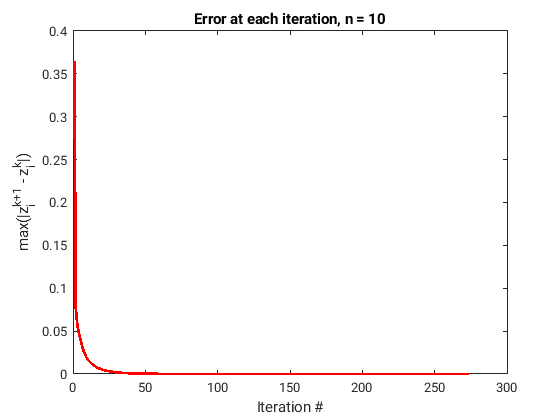

n = 20


------------------------------


Iterations Required = 826


The decision points are:


         0
    0.0500
    0.1000
    0.1499
    0.1999
    0.2499
    0.2999
    0.3499
    0.3998
    0.4498
    0.4998
    0.5498
    0.5998
    0.6499
    0.6999
    0.7499
    0.7999
    0.8499
    0.9000
    0.9500
    1.0000



The quantizers are:


    0.0250
    0.0750
    0.1249
    0.1749
    0.2249
    0.2749
    0.3249
    0.3749
    0.4248
    0.4748
    0.5248
    0.5748
    0.6249
    0.6749
    0.7249
    0.7749
    0.8249
    0.8749
    0.9250
    0.9750



------------------------------


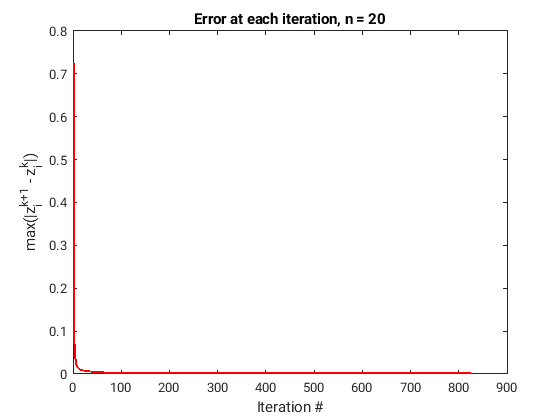

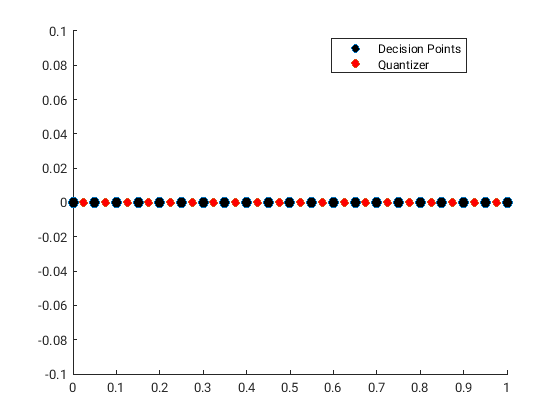

n = 40


------------------------------


Iterations Required = 2875


The decision points are:


         0
    0.0251
    0.0501
    0.0752
    0.1002
    0.1252
    0.1503
    0.1753
    0.2004
    0.2254
    0.2505
    0.2755
    0.3005
    0.3256
    0.3506
    0.3756
    0.4006
    0.4256
    0.4506
    0.4756
    0.5006
    0.5256
    0.5506
    0.5756
    0.6006
    0.6256
    0.6506
    0.6756
    0.7005
    0.7255
    0.7505
    0.7754
    0.8004
    0.8253
    0.8503
    0.8752
    0.9002
    0.9252
    0.9501
    0.9751
    1.0000



The quantizers are:


    0.0125
    0.0376
    0.0626
    0.0877
    0.1127
    0.1378
    0.1628
    0.1879
    0.2129
    0.2379
    0.2630
    0.2880
    0.3130
    0.3381
    0.3631
    0.3881
    0.4131
    0.4381
    0.4631
    0.4881
    0.5131
    0.5381
    0.5631
    0.5881
    0.6131
    0.6381
    0.6631
    0.6880
    0.7130
    0.7380
    0.7629
    0.7879
    0.8129
    0.8378
    0.8628
    0.8877
    0.9127
    0.9376
    0.9626
    0.9875



------------------------------


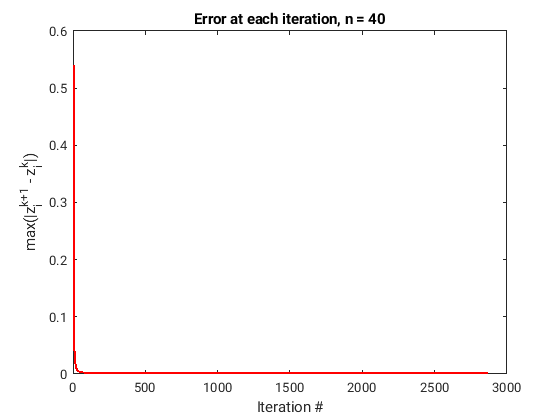

clc; clear; close all

%% Problem 1 - Part (a)

% define interval and density function
density = @(x) 1;
a = 0; b = 1;

% tolerance
TOL = 1e-6;

% number of intervals
nlist = [10 20 40];
% for testing
% nlist =[5];

for k = 1:length(nlist)

    n = nlist(k);

    % iteration counter
    iter = 0;

    % initial guess for quantizer = 'n' random values
    z = a + (b-a)*rand(n,1);
    z = z';

    % container for decision points
    d = [a, zeros(1, n-1), b];

    % container for updated quantizer
    z_new = zeros(1, n);

    while (true)

        % update iteration counter
        iter = iter + 1;

        % update decision points
        for i = 2:n
            d(i) = (z(i) + z(i-1))/2;
        end

        % update quantizer
        for i = 1:n
            f = @(x) x.*density(x);
            num = GaussQuad(d(i), d(i+1), f);
            denum = GaussQuad(d(i), d(i+1), density);
            z_new(iter, i) = num/denum;
        end

        % check for convergence
        err(iter) = max(abs(z_new(iter, :) - z));
        if (err(iter) < TOL)
            break
        end

        % update z
        z = z_new(iter, :);

        %% for debugging
        %% print info
        %fprintf('------------------------------\n')
        %fprintf('Iteration # = %d\n', iter)
        %fprintf('The decision points are:\n')
        %disp(d')
        %fprintf('The quantizers are:\n')
        %disp(z')
        %fprintf('------------------------------\n')

    end

    % print final results
    fprintf('n = %d\n', n)
    fprintf('------------------------------\n')
    fprintf('Iterations Required = %d\n', iter)
    fprintf('The decision points are:\n')
    disp(d')
    fprintf('The quantizers are:\n')
    disp(z')
    fprintf('------------------------------\n')
    totaliter(k) = iter;

    % plot errors
    figure()
    plot(1:iter, err(1:iter), 'r-', 'LineWidth', 2);
    xlabel('Iteration #')
    ylabel('max(|z_i^{k+1} - z_i^k|)')
    titlestring = ['Error at each iteration, n = ', num2str(n)];
    title(titlestring)

    % plot of quantizer (n = 20)
    if (n == 20)
        figure()
        title('Quantizer (n = 20)')
        scatter(d, zeros(size(d)), 60, 'MarkerFaceColor', 'black')
        ylim([-0.1, 0.1])
        hold on
        xlim([a b])
        scatter(z, zeros(size(z)), 40, 'MarkerFaceColor', 'red')
        legend('Decision Points', 'Quantizer', 'location', 'best')
    end

end


% determine rate of convergence
y = log(max(abs(z_new(2:end-2, :) - z)));
x = log(max(abs(z_new(1:end-3, :) - z)));
p = polyfit(x, y, 1);
fprintf('Rate of convergence = %g\n', p(1))

Rate of convergence = 0.957113


## `1b`

******************************


n = 10


------------------------------


Iterations Required = 100


The decision points are:


   -1.0000
   -0.6439
   -0.4410
   -0.2795
   -0.1361
   -0.0000
    0.1361
    0.2795
    0.4410
    0.6439
    1.0000



The quantizers are:


   -0.7599
   -0.5279
   -0.3540
   -0.2050
   -0.0672
    0.0672
    0.2050
    0.3540
    0.5279
    0.7599



******************************


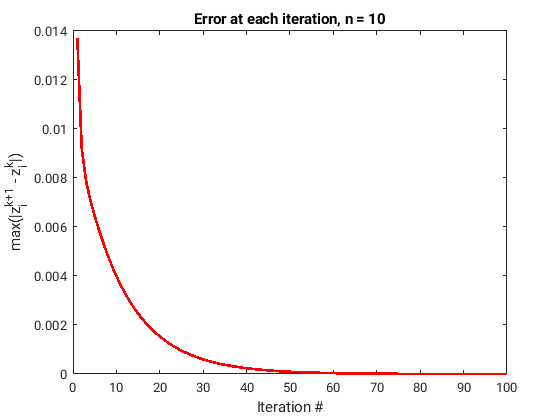

******************************


n = 20


------------------------------


Iterations Required = 328


The decision points are:


   -1.0000
   -0.7937
   -0.6544
   -0.5434
   -0.4481
   -0.3626
   -0.2838
   -0.2095
   -0.1381
   -0.0686
   -0.0000
    0.0686
    0.1381
    0.2095
    0.2838
    0.3626
    0.4481
    0.5434
    0.6544
    0.7937
    1.0000



The quantizers are:


   -0.8725
   -0.7149
   -0.5940
   -0.4927
   -0.4034
   -0.3219
   -0.2457
   -0.1732
   -0.1030
   -0.0342
    0.0342
    0.1030
    0.1732
    0.2457
    0.3219
    0.4034
    0.4927
    0.5940
    0.7149
    0.8725



******************************


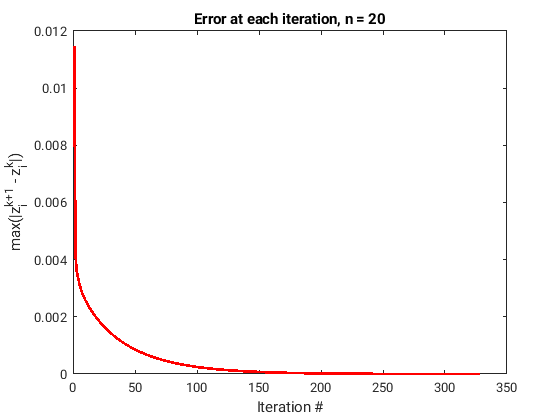

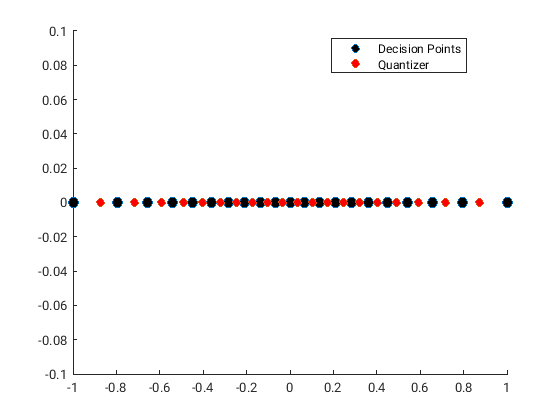

******************************


n = 40


------------------------------


Iterations Required = 1080


The decision points are:


   -1.0000
   -0.8863
   -0.7974
   -0.7228
   -0.6578
   -0.5995
   -0.5462
   -0.4967
   -0.4503
   -0.4064
   -0.3645
   -0.3242
   -0.2852
   -0.2474
   -0.2105
   -0.1744
   -0.1388
   -0.1037
   -0.0690
   -0.0344
   -0.0000
    0.0344
    0.0690
    0.1037
    0.1388
    0.1744
    0.2105
    0.2474
    0.2852
    0.3242
    0.3645
    0.4064
    0.4503
    0.4967
    0.5462
    0.5995
    0.6578
    0.7228
    0.7974
    0.8863
    1.0000



The quantizers are:


   -0.9351
   -0.8374
   -0.7573
   -0.6884
   -0.6272
   -0.5718
   -0.5206
   -0.4729
   -0.4278
   -0.3850
   -0.3439
   -0.3044
   -0.2661
   -0.2288
   -0.1923
   -0.1565
   -0.1212
   -0.0863
   -0.0517
   -0.0172
    0.0172
    0.0517
    0.0863
    0.1212
    0.1565
    0.1923
    0.2288
    0.2661
    0.3044
    0.3439
    0.3850
    0.4278
    0.4729
    0.5206
    0.5718
    0.6272
    0.6884
    0.7573
    0.8374
    0.9351



******************************


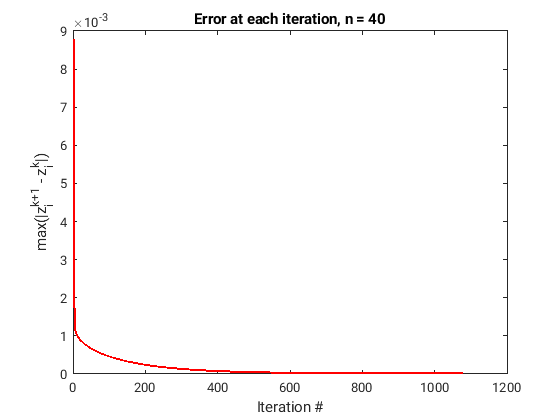

%% Problem 1 - Part (b)

clc; clear; close all

% define interval and density function
density = @(x) exp(-4*x.^2);
a = -1; b = 1;

% tolerance
TOL = 1e-6;

% number of intervals
nlist = [10 20 40];
% for testing
% nlist =[5];

for k = 1:length(nlist)

    n = nlist(k);

    % iteration counter
    iter = 0;

    % initial guess for quantizer = uniform grid
    z = linspace(a, b, n+2);
    z = z(2:end-1);

    % container for decision points
    d = [a, zeros(1, n-1), b];

    % container for updated quantizer
    z_new = zeros(1, n);

    while (true)

        % update iteration counter
        iter = iter + 1;

        % update decision points
        for i = 2:n
            d(i) = (z(i) + z(i-1))/2;
        end

        % update quantizer
        for i = 1:n
            f = @(x) x.*density(x);
            num = GaussQuad(d(i), d(i+1), f);
            denum = GaussQuad(d(i), d(i+1), density);
            z_new(iter, i) = num/denum;
        end

        % check for convergence
        err(iter) = max(abs(z_new(iter, :) - z));
        if (err(iter) < TOL)
            break
        end

        % update z
        z = z_new(iter, :);

        %% for debugging
        %% print info
        %fprintf('------------------------------\n')
        %fprintf('Iteration # = %d\n', iter)
        %fprintf('The decision points are:\n')
        %disp(d')
        %fprintf('The quantizers are:\n')
        %disp(z')
        %fprintf('------------------------------\n')

    end

    % print final results
    fprintf('******************************\n')
    fprintf('n = %d\n', n)
    fprintf('------------------------------\n')
    fprintf('Iterations Required = %d\n', iter)
    fprintf('The decision points are:\n')
    disp(d')
    fprintf('The quantizers are:\n')
    disp(z')
    fprintf('******************************\n')
    totaliter(k) = iter;

    % plot errors
    figure()
    plot(1:iter, err(1:iter), 'r-', 'LineWidth', 2);
    xlabel('Iteration #')
    ylabel('max(|z_i^{k+1} - z_i^k|)')
    titlestring = ['Error at each iteration, n = ', num2str(n)];
    title(titlestring)

    % plot of quantizer (n = 20)
    if (n == 20)
        figure()
        title('Quantizer (n = 20)')
        scatter(d, zeros(size(d)), 60, 'MarkerFaceColor', 'black')
        ylim([-0.1, 0.1])
        hold on
        xlim([a b])
        scatter(z, zeros(size(z)), 40, 'MarkerFaceColor', 'red')
        legend('Decision Points', 'Quantizer', 'location', 'best')
    end

end


% determine rate of convergence
y = log(max(abs(z_new(2:end-2, :) - z)));
x = log(max(abs(z_new(1:end-3, :) - z)));
p = polyfit(x, y, 1);
fprintf('Rate of convergence = %g\n', p(1))

Rate of convergence = 0.998312


## `1c`

`The error plots, rate of convergence, and the plot of quantizers, are all shown above in (a) and (b). We see that the ``Llyod algorithm converges linearly``.`

## `Q2. Global Method`

## `2a`

`We have`


$$F_i = 2z_i\int_{d_{i-1}}^{d_i} p(x) dx - 2\int_{d_{i-1}}^{d_i} xp(x) dx$$



$$\frac{\partial F_i}{\partial z_i} = 2\int_{d_{i-1}}^{d_i} p(x) dx + z_i(p(d_i) - p(d_{i-1})) - (d_ip(d_i) - d_{i-1}p(d_{i-1}))$$



$$\frac{\partial F_i}{\partial z_{i-1}} = -z_i p(d_{i-1}) + d_{i-1} p(d_{i-1})$$



$$\frac{\partial F_i}{\partial z_{i+1}} = z_i p(d_i) - d_{i}p(d_{i})$$


******************************


n = 10


------------------------------


Iterations Required = 56


The decision points are:


         0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000



The quantizers are:


    0.0500
    0.1500
    0.2500
    0.3500
    0.4500
    0.5500
    0.6500
    0.7500
    0.8500
    0.9500



******************************


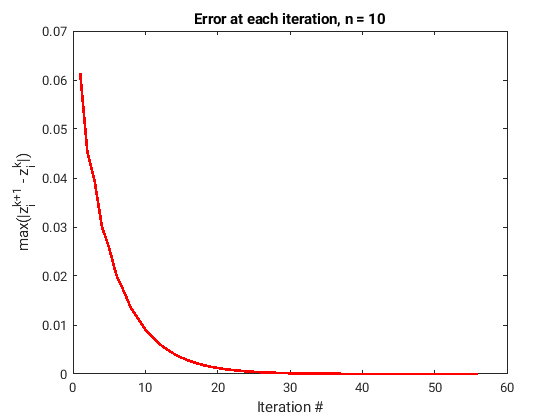

******************************


n = 20


------------------------------


Iterations Required = 105


The decision points are:


         0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500
    0.5000
    0.5500
    0.6000
    0.6500
    0.7000
    0.7500
    0.8000
    0.8500
    0.9000
    0.9500
    1.0000



The quantizers are:


    0.0250
    0.0750
    0.1250
    0.1750
    0.2250
    0.2750
    0.3250
    0.3750
    0.4250
    0.4750
    0.5250
    0.5750
    0.6250
    0.6750
    0.7250
    0.7750
    0.8250
    0.8750
    0.9250
    0.9750



******************************


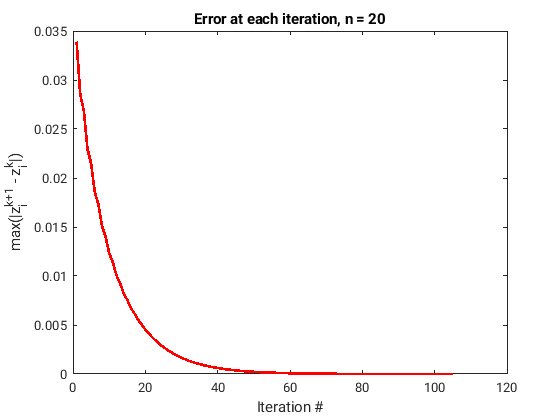

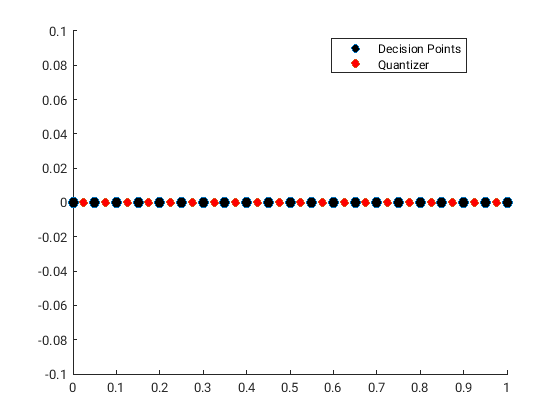

******************************


n = 40


------------------------------


Iterations Required = 195


The decision points are:


         0
    0.0250
    0.0500
    0.0750
    0.1000
    0.1250
    0.1500
    0.1750
    0.2000
    0.2250
    0.2500
    0.2750
    0.3000
    0.3250
    0.3500
    0.3750
    0.4000
    0.4250
    0.4500
    0.4750
    0.5000
    0.5250
    0.5500
    0.5750
    0.6000
    0.6250
    0.6500
    0.6750
    0.7000
    0.7250
    0.7500
    0.7750
    0.8000
    0.8250
    0.8500
    0.8750
    0.9000
    0.9250
    0.9500
    0.9750
    1.0000



The quantizers are:


    0.0125
    0.0375
    0.0625
    0.0875
    0.1125
    0.1375
    0.1625
    0.1875
    0.2125
    0.2375
    0.2625
    0.2875
    0.3125
    0.3375
    0.3625
    0.3875
    0.4125
    0.4375
    0.4625
    0.4875
    0.5125
    0.5375
    0.5625
    0.5875
    0.6125
    0.6375
    0.6625
    0.6875
    0.7125
    0.7375
    0.7625
    0.7875
    0.8125
    0.8375
    0.8625
    0.8875
    0.9125
    0.9375
    0.9625
    0.9875



******************************


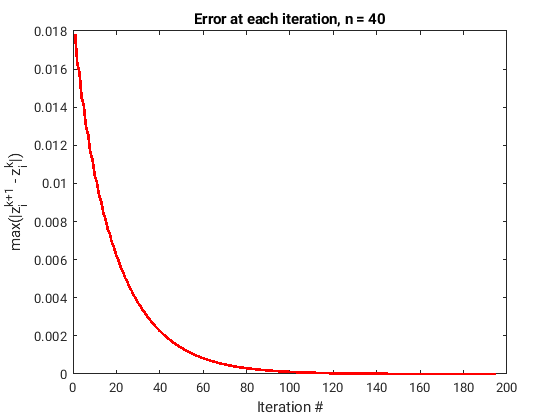

%% Problem 2 - Part(a)

clear;

% define interval and density function
density = @(x) 1;
a = 0; b = 1;

% tolerance
TOL = 1e-6;

% number of intervals
nlist = [10 20 40];
% for testing
% nlist =[5];

for k = 1:length(nlist)

    n = nlist(k);

    % iteration counter
    iter = 0;

    % initial guess for quantizer
    z = linspace(a, b, n+2);
    z = z(2:end-1);

    % container for decision points
    d = [a, zeros(1, n-1), b];

    % container for updated quantizer
    z_new = zeros(1, n);

    while (true)

        % update iteration counter
        iter = iter + 1;

        % update decision points
        for i = 2:n
            d(i) = (z(i) + z(i-1))/2;
        end

        % update quantizer - Newton's Method
        % construct DF matrix
        DF = zeros(n, n);
        for i = 1:n
            DF(i, i) = 2*GaussQuad(d(i), d(i+1), density) + ...
                        z(i)*(density(d(i+1)) - density(d(i))) - ...
                        (d(i+1)*density(d(i+1)) - d(i)*density(d(i)));
            if (i > 1)
                DF(i, i-1) = -z(i)*density(d(i)) + d(i)*density(d(i));
            end
            if (i < n)
                DF(i, i+1) = z(i)*density(d(i+1)) - d(i+1)*density(d(i+1));
            end
        end
        % construct F vector
        F = zeros(n, 1);
        f = @(x) x.*density(x);
        for i = 1:n
            F(i) = 2*z(i)*GaussQuad(d(i), d(i+1), density) - 2*GaussQuad(d(i), d(i+1), f);
        end
        % compute delta_z
        delta_z = DF\((-1)*F);
        % update quantizer
        z_new(iter, :) = z + delta_z';

        % check for convergence
        err(iter) = max(abs(z_new(iter, :) - z));
        if (err(iter) < TOL)
            break
        end

        % update z
        z = z_new(iter, :);

        %% for debugging
        %% print info
        %fprintf('------------------------------\n')
        %fprintf('Iteration # = %d\n', iter)
        %fprintf('The decision points are:\n')
        %disp(d')
        %fprintf('The quantizers are:\n')
        %disp(z')
        %fprintf('------------------------------\n')

    end

    % print final results
    fprintf('******************************\n')
    fprintf('n = %d\n', n)
    fprintf('------------------------------\n')
    fprintf('Iterations Required = %d\n', iter)
    fprintf('The decision points are:\n')
    disp(d')
    fprintf('The quantizers are:\n')
    disp(z')
    fprintf('******************************\n')
    totaliter(k) = iter;

    % plot errors
    figure()
    plot(1:iter, err(1:iter), 'r-', 'LineWidth', 2);
    xlabel('Iteration #')
    ylabel('max(|z_i^{k+1} - z_i^k|)')
    titlestring = ['Error at each iteration, n = ', num2str(n)];
    title(titlestring)

    % plot of quantizer (n = 20)
    if (n == 20)
        figure()
        title('Quantizer (n = 20)')
        scatter(d, zeros(size(d)), 60, 'MarkerFaceColor', 'black')
        ylim([-0.1, 0.1])
        hold on
        xlim([a b])
        scatter(z, zeros(size(z)), 40, 'MarkerFaceColor', 'red')
        legend('Decision Points', 'Quantizer', 'location', 'best')
    end

end


% determine rate of convergence
y = log(max(abs(z_new(2:end-2, :) - z)));
x = log(max(abs(z_new(1:end-3, :) - z)));
p = polyfit(x, y, 1);
fprintf('Rate of convergence = %g\n', p(1))

Rate of convergence = 1


## `2b`

n = 10


------------------------------


Iterations Required = 9


The decision points are:


   -1.0000
   -0.6439
   -0.4409
   -0.2795
   -0.1361
    0.0000
    0.1361
    0.2795
    0.4409
    0.6439
    1.0000



The quantizers are:


   -0.7599
   -0.5279
   -0.3540
   -0.2049
   -0.0672
    0.0672
    0.2049
    0.3540
    0.5279
    0.7599



------------------------------


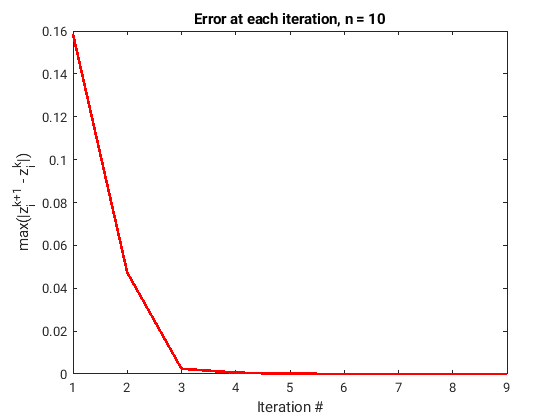

n = 20


------------------------------


Iterations Required = 15


The decision points are:


   -1.0000
   -0.7937
   -0.6544
   -0.5433
   -0.4480
   -0.3626
   -0.2838
   -0.2095
   -0.1381
   -0.0686
   -0.0000
    0.0686
    0.1381
    0.2095
    0.2838
    0.3626
    0.4480
    0.5433
    0.6544
    0.7937
    1.0000



The quantizers are:


   -0.8725
   -0.7148
   -0.5940
   -0.4927
   -0.4033
   -0.3219
   -0.2457
   -0.1732
   -0.1030
   -0.0342
    0.0342
    0.1030
    0.1732
    0.2457
    0.3219
    0.4033
    0.4927
    0.5940
    0.7148
    0.8725



------------------------------


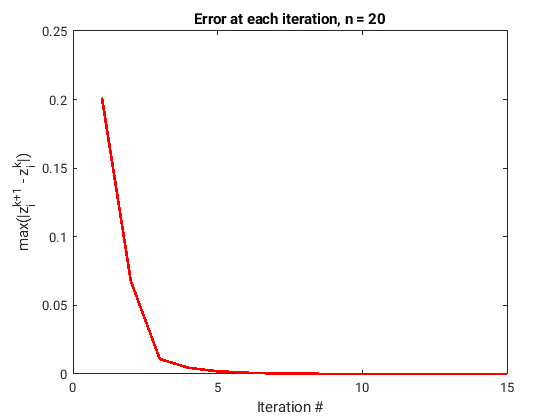

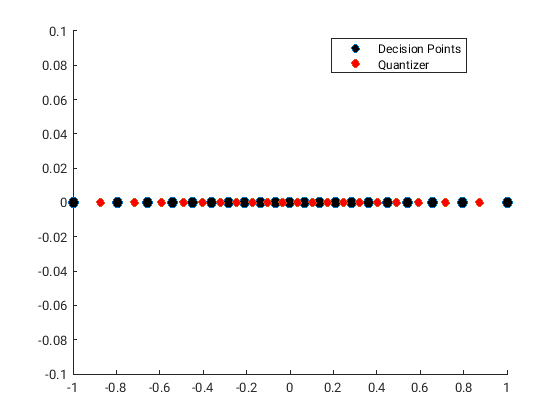

n = 40


------------------------------


Iterations Required = 27


The decision points are:


   -1.0000
   -0.8862
   -0.7973
   -0.7227
   -0.6577
   -0.5993
   -0.5460
   -0.4966
   -0.4502
   -0.4062
   -0.3643
   -0.3240
   -0.2851
   -0.2473
   -0.2104
   -0.1743
   -0.1387
   -0.1037
   -0.0689
   -0.0344
   -0.0000
    0.0344
    0.0689
    0.1037
    0.1387
    0.1743
    0.2104
    0.2473
    0.2851
    0.3240
    0.3643
    0.4062
    0.4502
    0.4966
    0.5460
    0.5993
    0.6577
    0.7227
    0.7973
    0.8862
    1.0000



The quantizers are:


   -0.9351
   -0.8373
   -0.7572
   -0.6883
   -0.6271
   -0.5716
   -0.5205
   -0.4727
   -0.4277
   -0.3848
   -0.3438
   -0.3043
   -0.2659
   -0.2286
   -0.1922
   -0.1564
   -0.1211
   -0.0862
   -0.0516
   -0.0172
    0.0172
    0.0516
    0.0862
    0.1211
    0.1564
    0.1922
    0.2286
    0.2659
    0.3043
    0.3438
    0.3848
    0.4277
    0.4727
    0.5205
    0.5716
    0.6271
    0.6883
    0.7572
    0.8373
    0.9351



------------------------------


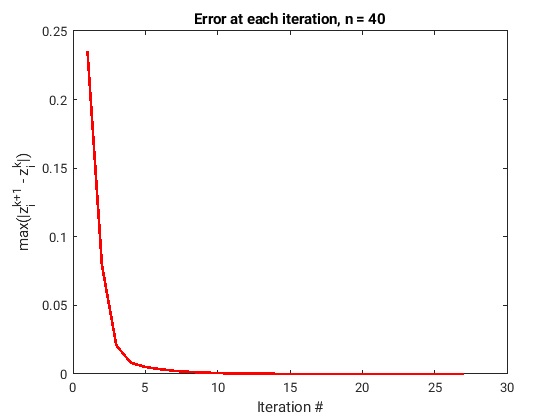

%% Problem 2 - Part(b)

clear;

% define interval and density function
density = @(x) exp(-4*x.^2);
a = -1; b = 1;

% tolerance
TOL = 1e-6;

% number of intervals
nlist = [10 20 40];
% for testing
% nlist =[5];

for k = 1:length(nlist)

    n = nlist(k);

    % iteration counter
    iter = 0;

    % initial guess for quantizer
    z = linspace(a, b, n+2);
    z = z(2:end-1);

    % container for decision points
    d = [a, zeros(1, n-1), b];

    % container for updated quantizer
    z_new = zeros(1, n);

    while (true)

        % update iteration counter
        iter = iter + 1;

        % update decision points
        for i = 2:n
            d(i) = (z(i) + z(i-1))/2;
        end

        % update quantizer - Newton's Method
        % construct DF matrix
        DF = zeros(n, n);
        for i = 1:n
            DF(i, i) = 2*GaussQuad(d(i), d(i+1), density) + ...
                        z(i)*(density(d(i+1)) - density(d(i))) - ...
                        (d(i+1)*density(d(i+1)) - d(i)*density(d(i)));
            if (i > 1)
                DF(i, i-1) = -z(i)*density(d(i)) + d(i)*density(d(i));
            end
            if (i < n)
                DF(i, i+1) = z(i)*density(d(i+1)) - d(i+1)*density(d(i+1));
            end
        end
        % construct F vector
        F = zeros(n, 1);
        f = @(x) x.*density(x);
        for i = 1:n
            F(i) = 2*z(i)*GaussQuad(d(i), d(i+1), density) - 2*GaussQuad(d(i), d(i+1), f);
        end
        % compute delta_z
        delta_z = DF\((-1)*F);
        % update quantizer
        z_new(iter, :) = z + delta_z';

        % check for convergence
        err(iter) = max(abs(z_new(iter, :) - z));
        if (err(iter) < TOL)
            break
        end

        % update z
        z = z_new(iter, :);

        %% for debugging
        %% print info
        %fprintf('------------------------------\n')
        %fprintf('Iteration # = %d\n', iter)
        %fprintf('The decision points are:\n')
        %disp(d')
        %fprintf('The quantizers are:\n')
        %disp(z')
        %fprintf('------------------------------\n')

    end

    % print final results
    fprintf('n = %d\n', n)
    fprintf('------------------------------\n')
    fprintf('Iterations Required = %d\n', iter)
    fprintf('The decision points are:\n')
    disp(d')
    fprintf('The quantizers are:\n')
    disp(z')
    fprintf('------------------------------\n')
    totaliter(k) = iter;

    % plot errors
    figure()
    plot(1:iter, err(1:iter), 'r-', 'LineWidth', 2);
    xlabel('Iteration #')
    ylabel('max(|z_i^{k+1} - z_i^k|)')
    titlestring = ['Error at each iteration, n = ', num2str(n)];
    title(titlestring)

    % plot of quantizer (n = 20)
    if (n == 20)
        figure()
        title('Quantizer (n = 20)')
        scatter(d, zeros(size(d)), 60, 'MarkerFaceColor', 'black')
        ylim([-0.1, 0.1])
        hold on
        xlim([a b])
        scatter(z, zeros(size(z)), 40, 'MarkerFaceColor', 'red')
        legend('Decision Points', 'Quantizer', 'location', 'best')
    end

end


% determine rate of convergence
y = log(max(abs(z_new(2:end-2, :) - z)));
x = log(max(abs(z_new(1:end-3, :) - z)));
p = polyfit(x, y, 1);
fprintf('Rate of convergence = %g\n', p(1))

Rate of convergence = 0.740564


## `2c`

`The error plots, rate of convergence, and the plot of quantizers, are all shown above in (a) and (b).` 

`The rate of convergence for Newton's iteration is not qaudratic as expected.` `It is linear for (a), and sub-linear for (b). `

`However, the number of iterations required to achieve the stopping tolerance is considerably lower than that required by Llyod's method. `

`Comparing the error plots, we can see that the error reduces drastically in the starting iterations with Newton's method, whereas in Lloyd's algorithm, the decrease is gradual.`

`In totality, Newton's method performs a lot better than Llyod's method. `

## `Q3. Adaptive Interpolation`

## `3(a,b) `

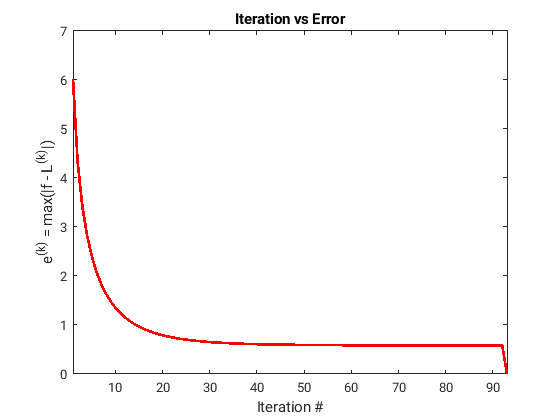

%% Problem 3 - Parts (a),(b)

% clear variables
clear;

% define interval and function
f = @(x) 1./(1 + 25*x.^2);
a = -1; b = 1;

% initial guess for quantizer = uniform grid
n = 10;
z = linspace(a, b, n+2);
z = z(2:end-1);
z = z';

% container for decision points
d = [a, zeros(1, n-1), b];

% container for updated quantizer
z_new = zeros(size(z));

% stopping tolerance
TOL = 1e-6;

% iteration counter
iter = 0;

% density function
density = @(x) 1./(pi*sqrt(1 - x.^2));

% run Llyoyd iterations
while (true)

    % update iteration counter
    iter = iter + 1;

    % update decision points
    for i = 2:n
        d(i) = (z(i) + z(i-1))/2;
    end

    % update quantizer
    for i = 1:n
        func = @(x) x.*density(x);
        num = GaussQuad(d(i), d(i+1), func);
        denum = GaussQuad(d(i), d(i+1), density);
        z_new(i) = num/denum;
    end

    % check for convergence
    err(iter) = max(abs(z_new - z));
    if (err(iter) < TOL)
        break
    end

    % update z
    z = z_new;

    % construct Langrange interpolant, compute errors
    t = linspace(a, b, 100); % vector of points over which interpolant is evaluated
    L = zeros(size(t));

    for i = 1:length(t)
        for j = 1:length(z)
            num = 1; denum = 1;
            for k = 1:length(z)
                if j ~= k
                    num = num*(t(i) - z(k));
                    denum = denum*(z(j) - z(k));
                end
            end
            L(i) = L(i) + f(z(j))*num/denum;
        end
    end
    
    err(iter) = max(abs(L - f(t))); 
    
end

% plot error at each iteration
figure()
plot(1:iter, err(1:iter), 'r-', 'LineWidth', 2)
xlabel('Iteration #')
ylabel('e^{(k)} = max(|f - L^{(k)}|)')
title('Iteration vs Error')
xlim([1, iter])


% print final results
for i = 1:1
    fprintf('******************************\n')
    fprintf('n = %d\n', n)
    fprintf('------------------------------\n')
    fprintf('Iterations Required = %d\n', iter)
    fprintf('The decision points are:\n')
    disp(d')
    fprintf('The quantizers are:\n')
    disp(z)
    fprintf('******************************\n')
end

******************************


n = 10


------------------------------


Iterations Required = 93


The decision points are:


   -1.0000
   -0.8559
   -0.6611
   -0.4484
   -0.2263
    0.0000
    0.2263
    0.4484
    0.6611
    0.8559
    1.0000



The quantizers are:


   -0.9473
   -0.7644
   -0.5578
   -0.3389
   -0.1136
    0.1136
    0.3389
    0.5578
    0.7644
    0.9473



******************************


## `3c`

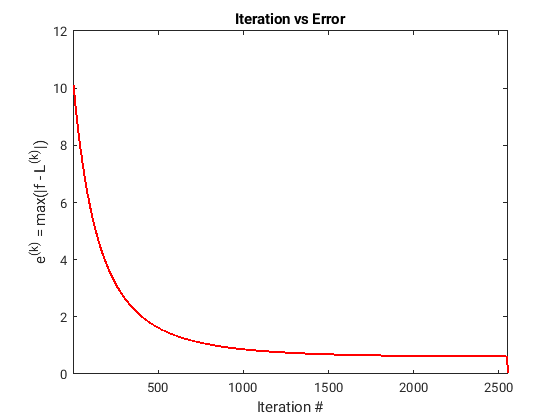

%% Problem 3 - Part (c)

% clear variables
clear;

% define interval and function
f = @(x) 1./(1 + 25*x.^2);
a = -1; b = 1;

% initial guess for quantizer = uniform grid
n = 10;
z = linspace(a, b, n+2);
z = z(2:end-1);
z = z';

% container for decision points
d = [a, zeros(1, n-1), b];

% container for updated quantizer
z_new = zeros(size(z));

% stopping tolerance
TOL = 1e-6;

% iteration counter
iter = 0;

% density function
density = @(x) 1./(pi*sqrt(1 - x.^2));

% run Llyoyd iterations
while (true)

    % update iteration counter
    iter = iter + 1;

    % update decision points
    for i = 2:n
        d(i) = (z(i) + z(i-1))/2;
    end

    % update quantizer
    % construct DF matrix
    DF = zeros(n, n);
    for i = 1:n
        % density function goes to Inf at endpoints, DF(1, 1) and DF(n, n)
        % are not defined.
        if (i ~= 1 && i ~= n)
            DF(i, i) = 2*GaussQuad(d(i), d(i+1), density) + ...
                        z(i)*(density(d(i+1)) - density(d(i))) - ...
                        (d(i+1)*density(d(i+1)) - d(i)*density(d(i)));
        end
        if (i > 1)
            DF(i, i-1) = -z(i)*density(d(i)) + d(i)*density(d(i));
        end
        if (i < n)
            DF(i, i+1) = z(i)*density(d(i+1)) - d(i+1)*density(d(i+1));
        end
        % DF(1,1) and DF(n, n) = Inf; DF(1, 1), DF(n, n) >>> other elements of DF
        % Increasing this value leads to convergence, but inaccurate results
        DF(1, 1) = 100;
        DF(n, n) = 100;
    end
    % construct F vector
    F = zeros(n, 1);
    func = @(x) x.*density(x);
    for i = 1:n
        F(i) = 2*z(i)*GaussQuad(d(i), d(i+1), density) - 2*GaussQuad(d(i), d(i+1), func);
    end
    % compute delta_z
    delta_z = DF\((-1)*F);
    % update quantizer
    z_new = z + delta_z;

    % check for convergence
    err(iter) = max(abs(z_new - z));
    if (err(iter) < TOL)
        break
    end

    % update z
    z = z_new;

    % construct Langrange interpolant, compute errors
    t = linspace(a, b, 100); % vector of points over which interpolant is evaluated
    L = zeros(size(t));

    for i = 1:length(t)
        for j = 1:length(z)
            num = 1; denum = 1;
            for k = 1:length(z)
                if j ~= k
                    num = num*(t(i) - z(k));
                    denum = denum*(z(j) - z(k));
                end
            end
            L(i) = L(i) + f(z(j))*num/denum;
        end
    end
    
    err(iter) = max(abs(L- f(t))); 
    
end

% plot error at each iteration
figure()
plot(1:iter, err(1:iter), 'r-', 'LineWidth', 2)
xlabel('Iteration #')
ylabel('e^{(k)} = max(|f - L^{(k)}|)')
title('Iteration vs Error')
xlim([1, iter])



% print final results
for i = 1:1
    fprintf('******************************\n')
    fprintf('n = %d\n', n)
    fprintf('------------------------------\n')
    fprintf('Iterations Required = %d\n', iter)
    fprintf('The decision points are:\n')
    disp(d')
    fprintf('The quantizers are:\n')
    disp(z)
    fprintf('******************************\n')
end

******************************


n = 10


------------------------------


Iterations Required = 2547


The decision points are:


   -1.0000
   -0.8554
   -0.6607
   -0.4481
   -0.2261
    0.0000
    0.2261
    0.4481
    0.6607
    0.8554
    1.0000



The quantizers are:


   -0.9468
   -0.7640
   -0.5575
   -0.3387
   -0.1135
    0.1135
    0.3387
    0.5575
    0.7640
    0.9468



******************************


## `3d`

`In this case, Newton's Method performs worse than Llyod's method. This is because of the fact that the density function evaluates to 'Inf' at the end points (-1 and 1) which is problematic when constructing the DF matrix. `

`Putting up a very large value for DF(1,1) and DF(n, n) (say 1e10) results in Newton's method converging in as low as 3 iterations, but the obtained solution is inaccurate. `

`A lower value of DF(1,1) and DF(n, n) (10-100) results in larger number of iterations, but the obtained solution is accurate, as can be confirmed by comparing the solutions obtained in 3(a).`

`We also note that the quantizers are good Lagrange points, and avoid Runge's phenomenon. The max. error is of the order of 1e-7. Hence, the quantizers can be used as Lagrange nodes for interpolation purposes.`

## `Function Definitions`

function Q = GaussQuad(a, b, f)

    % this function computes the quadrature of a function f
    % over [a, b], using the 5-point Gaussian Quadrature Rule

    % Gaussian Qudrature - nodes and weights
    nodes = [-sqrt(5 + 2*sqrt(10/7))/3, -sqrt(5 - 2*sqrt(10/7))/3, 0, ...
              sqrt(5 - 2*sqrt(10/7))/3, sqrt(5 + 2*sqrt(10/7))/3];
    weights = [(322 - 13*sqrt(70))/900 (322 + 13*sqrt(70))/900, 128/225, ...
               (322 + 13*sqrt(70))/900, (322 - 13*sqrt(70))/900];

    % transform limits
    points = 0.5*((b-a)*nodes + a + b);
    % jacobian
    j = (b-a)/2;
    % compute quadrature
    Q = sum(weights.*f(points)*j);

end